%=========================================================================
% Lecture 16: In Class Tutorial
%
% This function calculates the radial equilibrium function for an axially 
% stretched and pressurized thick wall vessel and is part of the set of 
% equations you will implement for your vasculature project
%
% Input data: 
%   luminal pressure (Pi), axial stretch (lambdaz_v) 
%   material parameters, radii in ktf (Ri, Ro)
%
% Output data:
%   approximation of the outer radius, ro
%
% The inverse solution of the radial equilibrium involves finding
% the root of the equation:
%   Pi - int_{ri}^{ro} (tqq-trr)/r dr = 0
%=========================================================================

% Clean environemnts
close all, clear all, clc

Load and Define INPUT DATA


% Control refers to a age-matched healthy model
control_data = load("Input_HypertensionControl_ATA.mat");
test_data = load("Input_Hypertension_ATA.mat");

% Obtains material parameters
material_control = control_data.estimated_parameters;
material_test = test_data.estimated_parameters;

% Loads control parameters
control_lambdaz_exp = control_data.data_kl.lambdaz_exp;
control_Psys_exp = control_data.data_kl.Psys_exp;
control_ref_outer_radius = control_data.data_ktf.or_exp;
control_ref_inner_radius = control_data.data_ktf.ir_exp;
control_thickness = control_data.data_ktf.h_exp;

% Load test parameters (hypertensions)
test_lambdaz_exp = test_data.data_kl.lambdaz_exp;
test_Psys_exp = test_data.data_kl.Psys_exp;
test_ref_outer_radius = test_data.data_ktf.or_exp;
test_ref_inner_radius = test_data.data_ktf.ir_exp;
test_thickness = test_data.data_ktf.h_exp;

%% Solve the equilibrium equation
% Equilibrium equation for a pressurized and axially stretched vessel
% Unknown: outer radius, ro
% ro will be estimated as the roots of the equilibrium equation

H=cell(1,2);
H{1,1}=@equilibrium_r_or_loaded; %handle to equilibrium equation 
H{1,2}=@equilibrum_z_fz_loaded;

% Parameter to be estimated in loaded configuration is the outer radius (ro) 
% x0 is the initial guess for ro based on the input experimental data

       

        
% DELIVERABLE - Plot Luminal Pressure vs Outer Diameter

% All luminal presure to be tested
luminalP = 10:5:140;

% Stretches to be modeled
control_axialStretch = [control_lambdaz_exp, control_lambdaz_exp*1.05, control_lambdaz_exp*0.95];
test_axialStretch = [test_lambdaz_exp, test_lambdaz_exp*1.05, test_lambdaz_exp*0.95];

% Initialize radius result
control_or_est = zeros(3, length(luminalP));
test_or_est = zeros(3, length(luminalP));

% Initialize force results
control_fz_est = zeros(3, length(luminalP));
test_fz_est = zeros(3, length(luminalP));


% Loop through stretches
for stretch_index = 1:length(control_axialStretch)
    control_stretch = control_axialStretch(stretch_index)
    test_stretch = test_axialStretch(stretch_index)
    
    % Loop through pressures

    for P_index = 1:length(luminalP)

        % Current pressure being tested
        Pi = luminalP(P_index);

        % GET R USING NEWTON RAPHSON% 

        % Control
        control_r = Newton_Raphson(H{1,1}, control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch, Pi, material_control, ...
            control_ref_outer_radius); 
        % Save results
        control_or_est(stretch_index, P_index) = control_r;

        % Test
        test_r = Newton_Raphson(H{1,1}, test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, Pi, material_test, ...
            test_ref_outer_radius); 
        % Save results
        test_or_est(stretch_index, P_index) = test_r;


        % GET CURRENT F WITH OPTIMIZED R

        % Control
        control_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch,material_control,control_r);

        % Test
        test_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, material_test,test_r);
        
        
    end

end

control_stretch = 1.9761

test_stretch = 1.4955

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1662

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1244

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.2377

---
Maximum number of iterations reached
---


iter = 1000

f = 3.3751e-14

x = 1.1721

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2804

---
Maximum number of iterations reached
---


iter = 1000

f = 6.3949e-14

x = 1.2000

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2295e+26

x = 2.6793

---
Maximum number of iterations reached
---


iter = 1000

f = 8.5265e-14

x = 1.2191

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5681e+50

x = 3.1169

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5987e-13

x = 1.2333

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0501e+86

x = 3.5511

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-13

x = 1.2445

---
Maximum number of iterations reached
---


iter = 1000

f = 8.7626e+137

x = 3.9852

---
Maximum number of iterations reached
---


iter = 1000

f = 1.6342e-13

x = 1.2537

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4176e+210

x = 4.4194

---
Maximum number of iterations reached
---


iter = 1000

f = 1.9185e-13

x = 1.2614

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4158e-13

x = 1.2680

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2633e-13

x = 1.2738

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.1974e-13

x = 1.2789

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 6.1107e-13

x = 1.2835

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 2.2737e-13

x = 1.2877

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -3.1264e-13

x = 1.2915

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -7.8160e-13

x = 1.2950

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -9.3792e-13

x = 1.2982

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -8.1002e-13

x = 1.3012

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -7.3896e-13

x = 1.3040

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -9.5213e-13

x = 1.3066

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -1.0090e-12

x = 1.3090

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4054e-13

x = 1.3113

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-12

x = 1.3135

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 8.3844e-13

x = 1.3156

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7337e-12

x = 1.3175

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2506e-12

x = 1.3194

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.6769e-12

x = 1.3212

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5916e-12

x = 1.3229

control_stretch = 2.0749

test_stretch = 1.5703

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.1407

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.0915

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.2161

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4869e-14

x = 1.1469

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2609

---
Maximum number of iterations reached
---


iter = 1000

f = -2.8422e-14

x = 1.1788

---
Maximum number of iterations reached
---


iter = 1000

f = 3.6539e+21

x = 2.5454

---
Maximum number of iterations reached
---


iter = 1000

f = 5.6843e-14

x = 1.2002

---
Maximum number of iterations reached
---


iter = 1000

f = 2.0460e+41

x = 2.9713

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-13

x = 1.2158

---
Maximum number of iterations reached
---


iter = 1000

f = 5.1715e+70

x = 3.3833

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7053e-13

x = 1.2280

---
Maximum number of iterations reached
---


iter = 1000

f = 1.8396e+113

x = 3.7953

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-13

x = 1.2379

---
Maximum number of iterations reached
---


iter = 1000

f = 2.3828e+172

x = 4.2072

---
Maximum number of iterations reached
---


iter = 1000

f = 2.7711e-13

x = 1.2461

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1330e+251

x = 4.6191

---
Maximum number of iterations reached
---


iter = 1000

f = 2.5580e-13

x = 1.2532

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -4.1922e-13

x = 1.2594

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -3.9790e-13

x = 1.2648

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -2.7001e-13

x = 1.2697

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -2.9843e-13

x = 1.2741

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -4.9738e-13

x = 1.2781

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -3.1264e-13

x = 1.2817

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = -7.8160e-13

x = 1.2851

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 9.0949e-13

x = 1.2882

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 8.3844e-13

x = 1.2912

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 7.9581e-13

x = 1.2939

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 7.3896e-13

x = 1.2964

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 4.8317e-13

x = 1.2988

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2648e-12

x = 1.3011

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5632e-12

x = 1.3032

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5632e-12

x = 1.3053

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.6485e-12

x = 1.3072

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3358e-12

x = 1.3091

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.6485e-12

x = 1.3108

control_stretch = 1.8773

test_stretch = 1.4207

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.1855

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1394

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.2542

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.1824

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.2956

---
Maximum number of iterations reached
---


iter = 1000

f = 5.6843e-14

x = 1.2084

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4505e+28

x = 2.7184

---
Maximum number of iterations reached
---


iter = 1000

f = 9.2371e-14

x = 1.2265

---
Maximum number of iterations reached
---


iter = 1000

f = 7.9544e+52

x = 3.1593

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1041e+06

x = 1.6081

---
Maximum number of iterations reached
---


iter = 1000

f = 3.4610e+90

x = 3.5979

---
Maximum number of iterations reached
---


iter = 1000

f = 1.8009e+12

x = 1.7801

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0939e+145

x = 4.0365

---
Maximum number of iterations reached
---


iter = 1000

f = 5.4006e+16

x = 1.8849

---
Maximum number of iterations reached
---


iter = 1000

f = 6.0143e+220

x = 4.4752

---
Maximum number of iterations reached
---


iter = 1000

f = 3.6111e+21

x = 1.9776

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3007e+26

x = 2.0620

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2472e+32

x = 2.1383

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.2564e+37

x = 2.2066

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 6.5207e+42

x = 2.2670

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 7.0670e+47

x = 2.3196

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0344e+52

x = 2.3647

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.9665e+56

x = 2.4024

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2829e+60

x = 2.4330

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8618e+62

x = 2.4569

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.1984e+65

x = 2.4743

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0816e+66

x = 2.4856

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5422e+67

x = 2.4911

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.6097e+67

x = 2.4913

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.8990e+66

x = 2.4864

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 2.5116e+65

x = 2.4769

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 5.0349e+63

x = 2.4631

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 3.7226e+61

x = 2.4454

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2097e+59

x = 2.4242

---
Maximum number of iterations reached
---


iter = 1000

f = NaN

x = NaN

---
Maximum number of iterations reached
---


iter = 1000

f = 2.0570e+56

x = 2.3998

% Find diameter
control_diam = control_or_est .* 2

control_diam =     2.3325    2.4754    2.5608    5.3586    6.2338    7.1021    7.9704    8.8388       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.2813    2.4322    2.5218    5.0907    5.9426    6.7667    7.5905    8.4144    9.2383       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.3710    2.5085    2.5912    5.4368    6.3185    7.1958    8.0731    8.9503       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


test_diam = test_or_est .* 2

test_diam =     2.2489    2.3441    2.4001    2.4382    2.4666    2.4890    2.5073    2.5227    2.5360    2.5476    2.5579    2.5671    2.5754    2.5830    2.5900    2.5964    2.6024    2.6079    2.6131    2.6180    2.6226    2.6270    2.6311    2.6350    2.6388    2.6423    2.6457
    2.1830    2.2938    2.3577    2.4003    2.4316    2.4559    2.4757    2.4923    2.5064    2.5188    2.5297    2.5394    2.5482    2.5562    2.5635    2.5702    2.5765    2.5823    2.5878    2.5929    2.5977    2.6022    2.6065    2.6106    2.6144    2.6181    2.6216
    2.2788    2.3648    2.4169    2.4530    3.2163    3.5602    3.7697    3.9552    4.1240    4.2766    4.4132    4.5340    4.6392    4.7293    4.8047    4.8660    4.9137    4.9486    4.9712    4.9822    4.9825    4.9728    4.9537    4.9262    4.8908    4.8484    4.7996


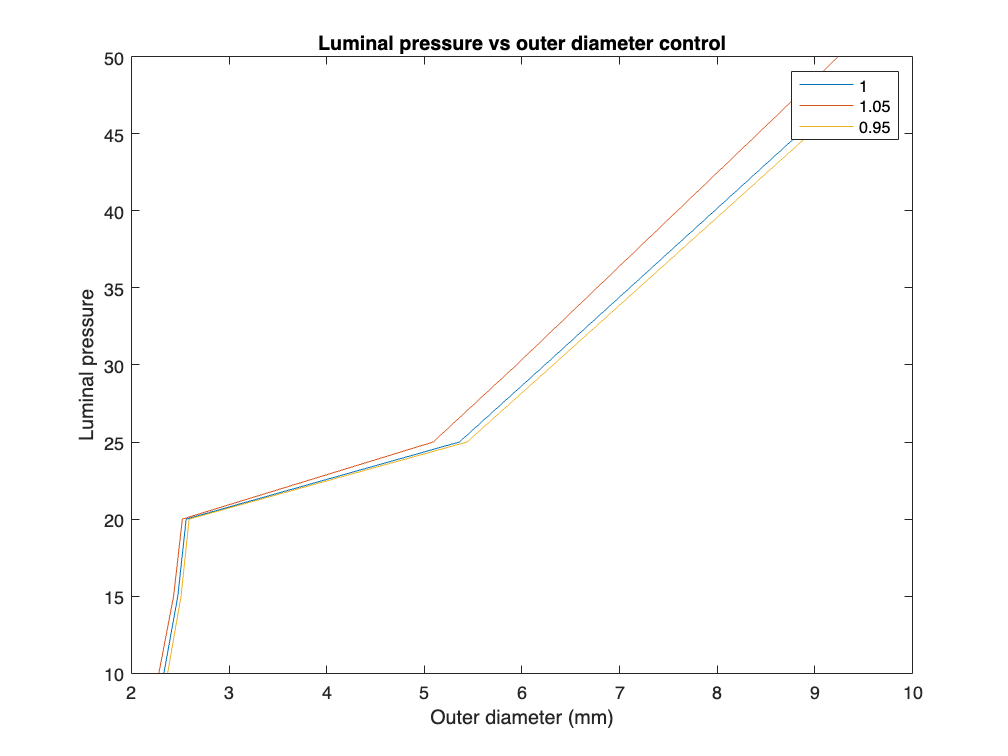


% Plot
figure()
plot(control_diam(1,:),luminalP, control_diam(2,:),luminalP, control_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter control")

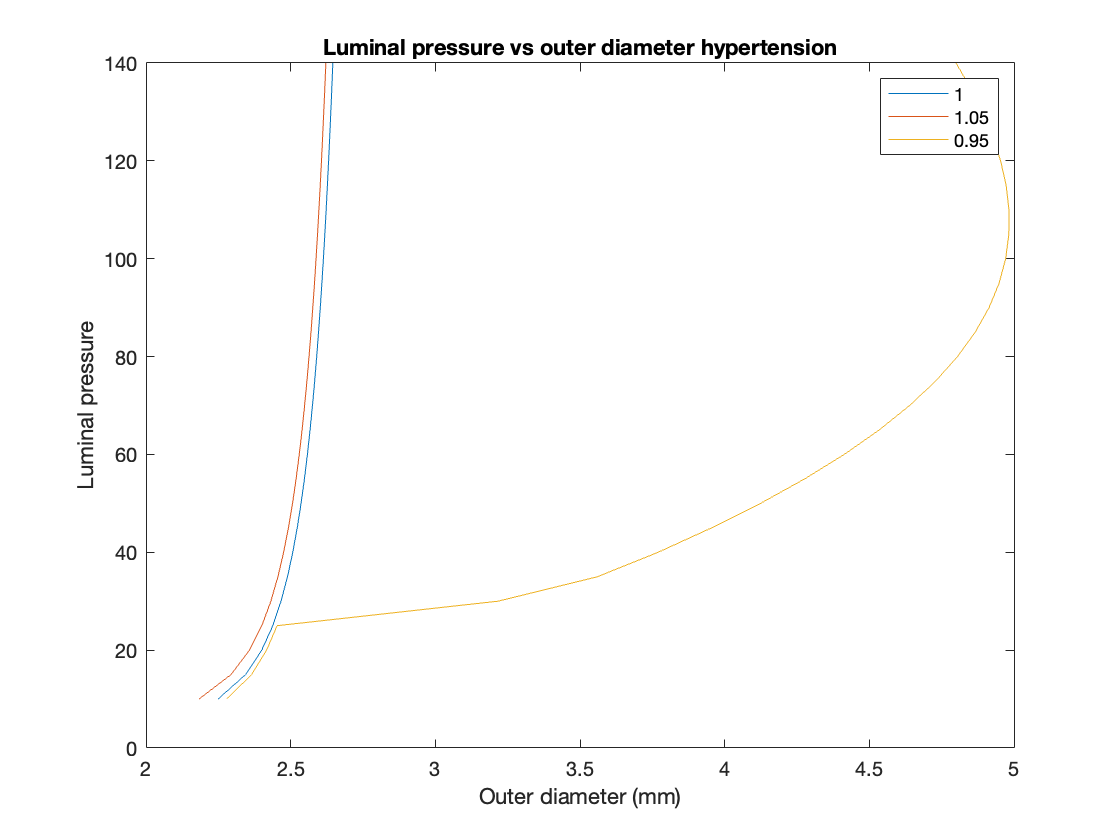


% Plot
figure()
plot(test_diam(1,:),luminalP, test_diam(2,:),luminalP, test_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter hypertension")

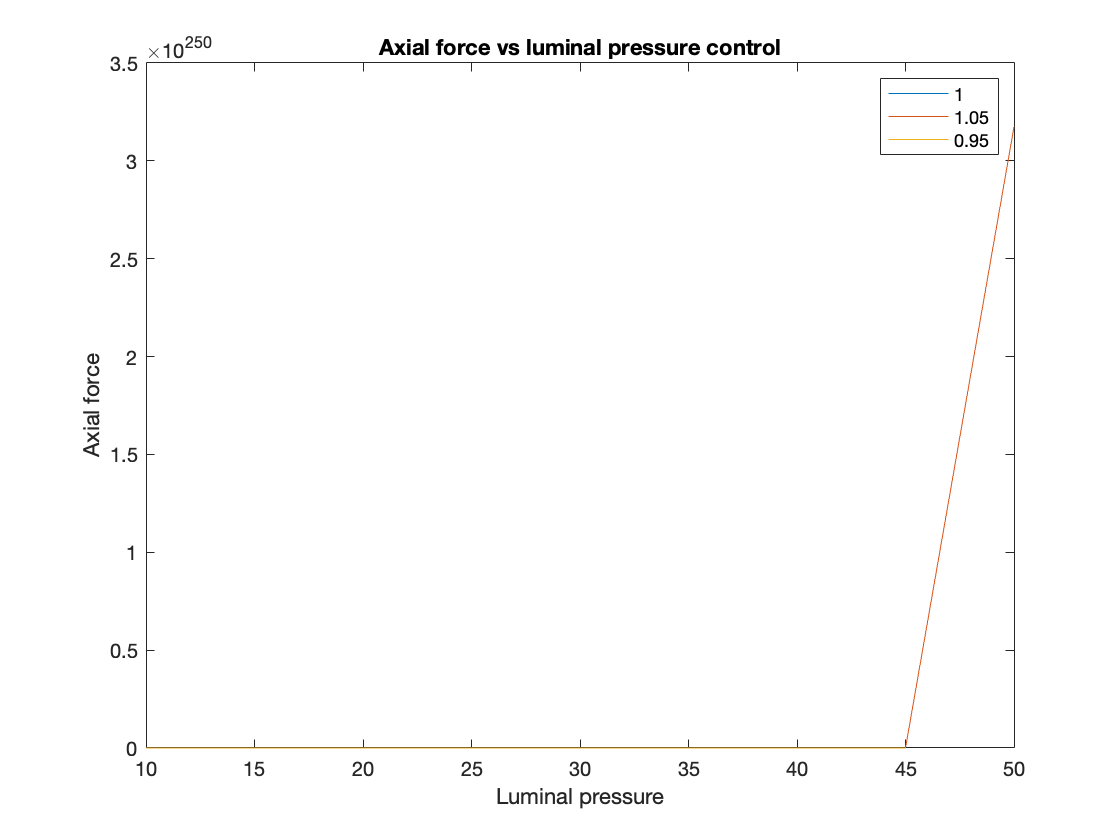


% Plot
figure()
plot(luminalP, control_fz_est(1,:),luminalP, control_fz_est(2,:),luminalP, control_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure control")

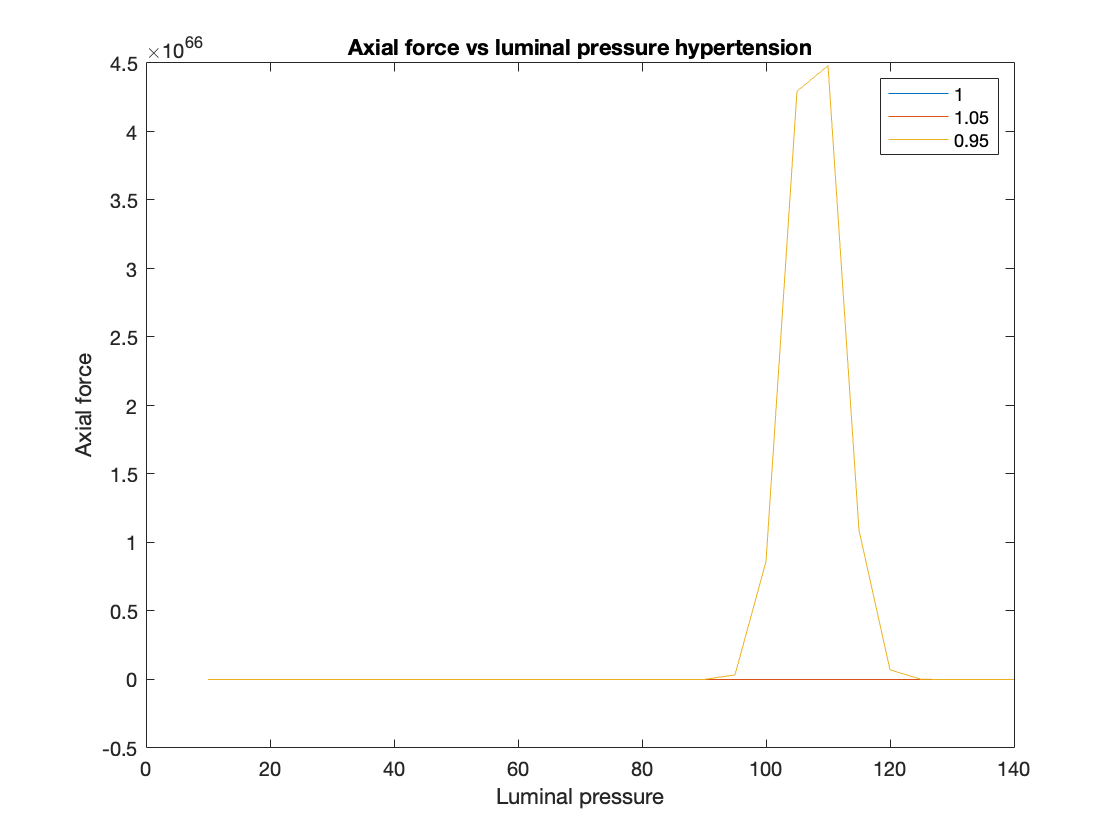


% Plot
figure()
plot(luminalP, test_fz_est(1,:),luminalP, test_fz_est(2,:),luminalP, test_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure hypertension")